%Code to model 6DOF primarily using the paper: 
%https://www.researchgate.net/publication/327064480_Experimental_and_numerical_study_of_chaff_cloud_kinetic_performance_under_the_impact_of_high_speed_airflow
%Completed by BS
clear;

%initialising of parameters (ie angles, coefficients)
theta = pi/2; %pitch angle (radians)
Psi_s = pi/3; %yaw? angle (radians)
zeta = 2*pi % (radians)

zeta = 6.2832

psi = pi/2 %(radians)

psi = 1.5708


%unit vectors defined
n_d = [(-sin(zeta)*cos(psi)), (cos(zeta)),  (sin(zeta)*sin(psi))] %unit vector of

n_d =     0.0000    1.0000   -0.0000


n_v = [(cos(theta)*cos(psi)), sin(theta), (-cos(theta)*sin(psi))] %unit vector of velocity 

n_v =     0.0000    1.0000   -0.0000


n_y = [cross(n_v, (cross(n_v,n_d)*dot(n_v,n_d)))/norm(cross(n_v,(cross(n_v,n_d)*dot(n_v,n_d))))] %unit vector of lift 

n_y =    -0.0000    0.0000    1.0000




%variables for kinematics found from unit vectors
gamma_s = -asin((((n_v(3)*n_y(1))-(n_v(1)*n_y(3))*n_y(2))/(sqrt(((n_v(1))^2)+(n_v(3))^2)*abs(n_y(2)))))% roll angle (radians)

gamma_s = -1.5708


%constants 

m - Mass of chaff fibre (grams)

rho - Atmospheric density (assumed constant kg/m^3)

aOne - Distance Impact Factor

fValue - Proportionality constant

dt - Time step value (seconds)

maxTime - Time simulation runs for (seconds)

numberOfChaff - Number of Chaff Fibres

sizeOfChaff - Size of Chaff in output graph

V - initial velocity of chaff

radius - Radius of sphere of chaff

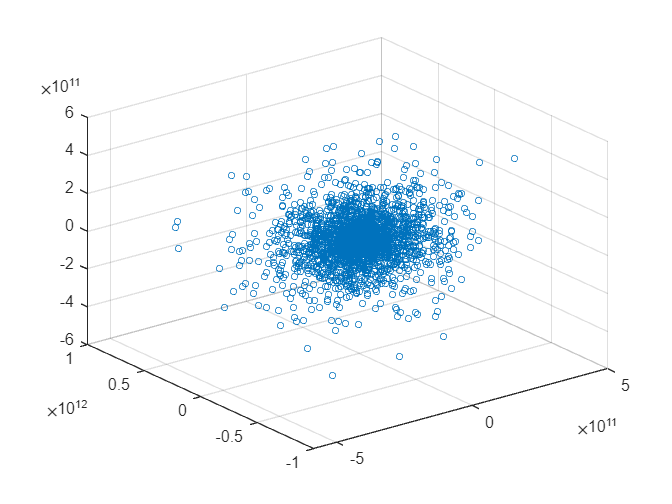

m = 0.09; %mass of chaff (g)
g = 9.81; %accleration due to gravity (ms^2)
rho = 8;  %atmospheric density (assumed constant)
aOne=1.5;  %Distance impact factor
fValue=0.1; %Proportionality coefficient
dt=0.1; %Time step
maxTime = 380; %Final time of the simulation
numberOfChaff = 2810; %Number of chaff fibres
sizeOfChaff = 15; %Size of chaff on th e graph
V = 30; %chaff velocity 
radius=3; %Radius of chaff
S = 4*pi*(radius)^2;%area of chaff (m^2) %want to treat like a sphere
 

kinematic_equations(gamma_s,aOne,fValue,0.52,0.82,dt,50,m,g,numberOfChaff,rho,S,sizeOfChaff,V)

function kinematic_equations(gamma_s,aOne,fValue,cXPrime,cYPrime,dt,maxTime,m,g,numberOfChaff,rho,S,sizeOfChaff,V)
      [cX,cY] = calculateAerodynamicInterferenceImpactFactors(aOne,fValue,cXPrime,cYPrime); %calls to function to calculate constants
      X = 0.5*cX*rho*(V^2)*S; %Calculates drag
      Y = 0.5*cY*rho*(V^2)*S; %Calculates lift
      theta = pi; % Pitch angle?
      xValues=[];
      yValues=[];
      zValues=[];
      PsiS = pi; % Heading angle
      %fps = 20;
      %output_file = '6DOF_animation.mp4';
      %video = VideoWriter(output_file, 'MPEG-4');
      %video.FrameRate = fps;
      %open(video);
for i = 1:1:numberOfChaff
    %Start each chaff with an initial coordinate of a random number between 0 and 1
    xValueCurrent = rand();
    yValueCurrent = rand();
    zValueCurrent = rand();
    for t = 0.0:dt:maxTime %Takes time steps between 0 and maxTime in steps of dt
        dV = ((-X - m*g*sin(theta))/m)*dt; %Change in velocity at each time step
        dTheta = ((Y*cos(gamma_s) - m*g*cos(theta))/m*V)*dt; %Change in theta at each time step
        dPsiS = ((-Y*sin(gamma_s))/m*V*cos(theta))*dt; %Change in Psi at each time step
        V = V+dV; %Update the velcocity value
        theta = theta + dTheta; %Update the theta value
        PsiS = PsiS + dPsiS; %update the psi value
        %Uses these new values of V, theta and Psi to find the change in the coordinate
        dX = V*cos(theta)*cos(PsiS)*dt;
        dY = V*sin(theta)*dt;
        dZ = -V*cos(theta)*sin(PsiS)*dt;
        %Changes the value of coordinate due to these change in coordinate
        xValueCurrent = xValueCurrent + dX;
        yValueCurrent = yValueCurrent + dY;
        zValueCurrent = zValueCurrent + dZ;
    end
    %Appends the coordinate values to an array to plot
    xValues = [xValues, xValueCurrent];
    yValues = [yValues, yValueCurrent];
    zValues = [zValues, zValueCurrent];
    
    %figure;
    %hold on;
    %grid on;
    %scatter3(xValues,yValues,zValues,sizeOfChaff);
    %view(3);
    %frame = getframe(gcf);
    %writeVideo(video,frame);
    %drawnow;
end
%close(video);
hold off;
%xValues
%yValues
%zValues
figure;
hold on;
grid on;
scatter3(xValues,yValues,zValues,sizeOfChaff); %Plots a scatter of the coordinates
view(3);
hold off;
end

function [cX,cY] = calculateAerodynamicInterferenceImpactFactors(aOne,fValue,cXPrime,cYPrime); %Function calculates cX and cY due to the constants f and a1 from paper
cX = 0.520*(1-aOne);
cY = 0.820*fValue*(1-aOne);
%a1 is distance impact factor and f is proportionality coefficient
end
